# Geoscience Data Analysis

*D. Hasterok (derrick.hasterok@adelaide.edu.au)*

*Dept. of Earth Sciences, University of Adelaide, North Terrace, Adelaide, SA 5005*

# 10 Interpolation, Extrapolation & Geospatial Analysis

addpath ../codes
addpath ../data

clear all;

## 10.1 Interpolation

Interpolation and the next section on extrapolation are about estimating the values of data between observations (interpolation) or outside the bounds of the data (extrapolation).  There are a few reasons we might want to do such operations: estimate the values at specific locations of interest; interpolate to even data spacing, which is necessary for many processing methods; and estimate to datasets at coincident locations for covariance analysis or modelling.  There are a number of methods for interpolation and a few common ones are discussed below.  Which method you choose can have a significant impact on the result.  The choice often depends on the type and nature of the data.  Some data should be smooth, e.g., gravity and magnetic fields, where polynomials and splines may be better choices whereas other types of measurements may not have steps and discontinuities, e.g., elevation (think cliffs or craggy mountain peaks), where linear or nearest neighbor is the preferred interpolation method.  Just remember that more complicated mathematical procedures do not always give more accurate results.

### 10.1.1 Nearest Neighbor

The nearest neighbor algorithm is nothing fancy.  It simply estimates the value at a given point by the value of the point that it is nearest to it.

### 10.1.2 Linear

The simplest interpolation scheme, interpolating using piecewise linear model.  The procedure is relatively straightforward:

- Suppose we have collected a set of observations, $S = \{(x_0,y_0), (x_1,y_1), \ldots, (x_N,y_N)\}$, where the sample locations (independent variable values) are sorted, i.e., $X = \{x_0 < x_1 < \cdots < x_N\}$.

- Find the two closest points, $x_i$ and $x_j$, on either side of the desired interpolation position, $\hat{x}_k$, by computing the distance between every point and the interpolated location—we don't actually have to compute every point because they are sorted.  We need to compute the signed distance, $d(x|\hat{x}_k) = x - \hat{x}_k$, and find the index, $i$, that satisfies $d(x_i|\hat{x}_k) = \min_{x_i \in X} |x_i - \hat{x}_k|$.  If $d_i = d(x_i|\hat{x}_k) = 0$, then the value of $y_k = y_i$, otherwise we will need to interpolate.  The index for the second index is determined from the sign of $d_i$, by $j = \begin{cases} {i - 1, & \text{sgn}\,(d_i) > 1 \\ i + 1, &  \text{sgn}\,(d_i) < 1 \end{cases}$.

- Determine the equation of a line that connects the two points $(x_i,y_i)$ and $(x_j,y_j)$.  To find the slope and intercept, $m_{ij} = \frac{y_j - y_i}{x_j - x_i}$ and $b_{ij} = m_{ij} x_i - y_i$.

- Compute the value of the line at $\hat{x}_k$ to find $\hat{y}_k$, $\hat{y}_k = m_{ij} \hat{x}_k + b_{ij}$.

- Repeat steps 2 to 4 for all $k$.

*Note: observations used to interpolate are often referred to as control points and you will find me using the two interchangeably.*

Like most techniques, MATLAB has a function to do the heavy lifting.

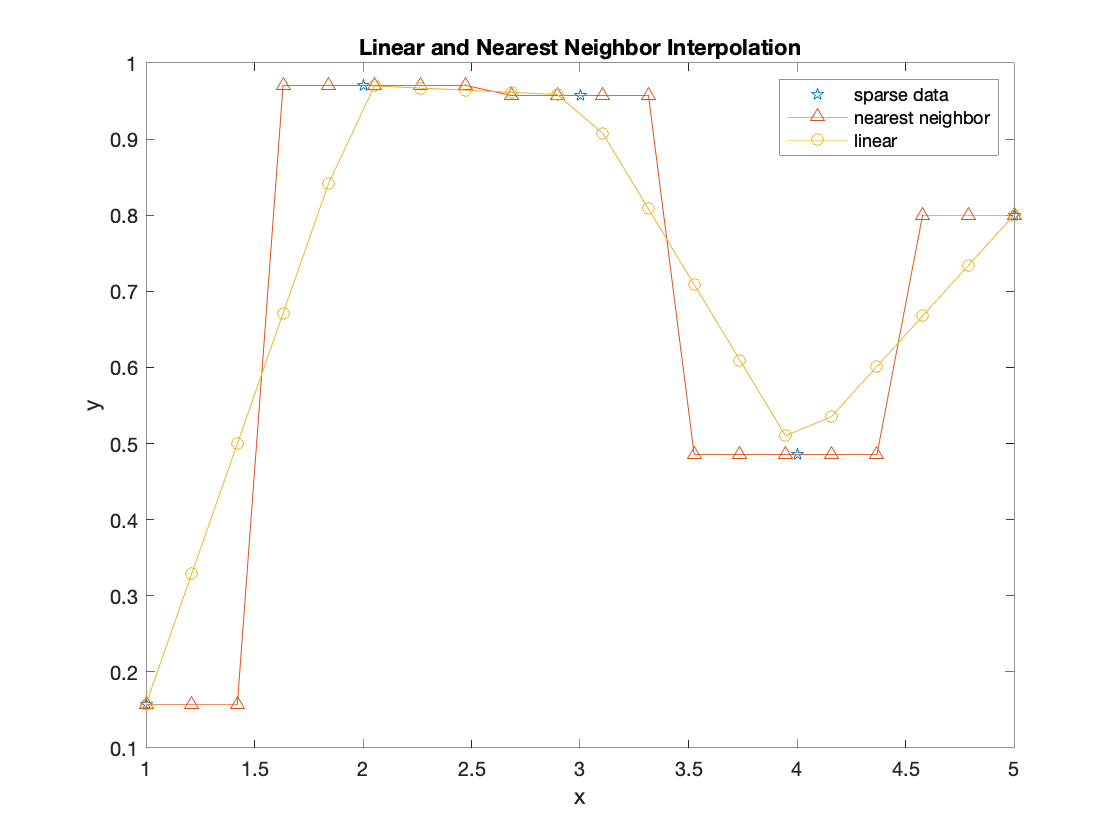

%Let's create a random dataset with a few points
Np = 5;

x = [1:5]';
y = rand([Np 1]);

% Now let's create a set of location to interpolate
xi = linspace(min(x),max(x),20)';

% interpolate using nearest neighbor
ynn = interp1(x,y,xi,'nearest');
% interpolate using linear
yi = interp1(x,y,xi,'linear');

figure;
plot(x,y,'p'); % the sparse random dataset
hold on;
plot(xi,ynn,'^-');  % nearest-neighbor interpolated points
plot(xi,yi,'o-');   % linear interpolated points
title('Linear and Nearest Neighbor Interpolation');
legend('sparse data','nearest neighbor','linear')
xlabel('x');
ylabel('y');

set(gca,'Box','on');

### 10.1.3 Polynomial

It is possible to fit a polynomial of order $N$ through any $N+1$ points.  You can fit an exact line through two points, and you can fit a unique quadratic through three points.  Determining the coefficients of an $N$ order polynomial,

$p(x) = a_{N}x^{N} + a_{N-1}x^{N-1} + \cdots + a_2 x^2 + a_1 x^1 + a_0$, with $N$ points from the set $S = \{(x_0,y_0), (x_1,y_1), \ldots, (x_N,y_N)\}$, is

$\pmatrix{1 & x_0 & x_0^2 & \cdots & x_0^{N} \cr 1 & x_1 & x_1^2 & \cdots & x_1^{N} \cr \vdots & \vdots & \vdots & \ddots & \vdots \cr 1 & x_N & x_N^2 & \cdots & x_N^{N} \cr} \pmatrix{a_0 \cr a_1 \cr \vdots \cr a_{N}} = \pmatrix{y_0 \cr y_1 \cr \vdots \cr y_N}$$,

which has exactly one solution.  The coefficients can then be solved by Gaussian elimination or simply by inverting ${\bf A}$ as the matrix is square.  However, the solution to this problem is well known and the interpolation can be determined without calculating the calculating the coefficients explicitly using the Lagrange polynomial solution:


$$p(x) = \sum_{i = 0}^N \left( \prod_{0 \leq j \leq N, j \neq i} \frac{x - x_j}{x_i - x_j} \right) y_i = \frac{(x - x_1) (x - x_2) \cdots (x - x_N)}{(x_0 - x_1) (x_0 - x_2) \cdots (x_0 - x_N)}y_0 + \frac{(x - x_0) (x - x_2) \cdots (x - x_N)}{(x_1 - x_0) (x_1 - x_2) \cdots (x_1 - x_N)}y_1 + \cdots + \frac{(x - x_0) (x - x_1) \cdots (x - x_{N-1})}{(x_N - x_0) (x_N - x_1) \cdots (x_N - x_{N-1})}y_N$$


Polynomial interpolation is not commonly used because it tends to have maxima and minima between the observations that can be fairly extreme and may not be warranted.  It also does not work well for smooth monotonic functions as we will show later.

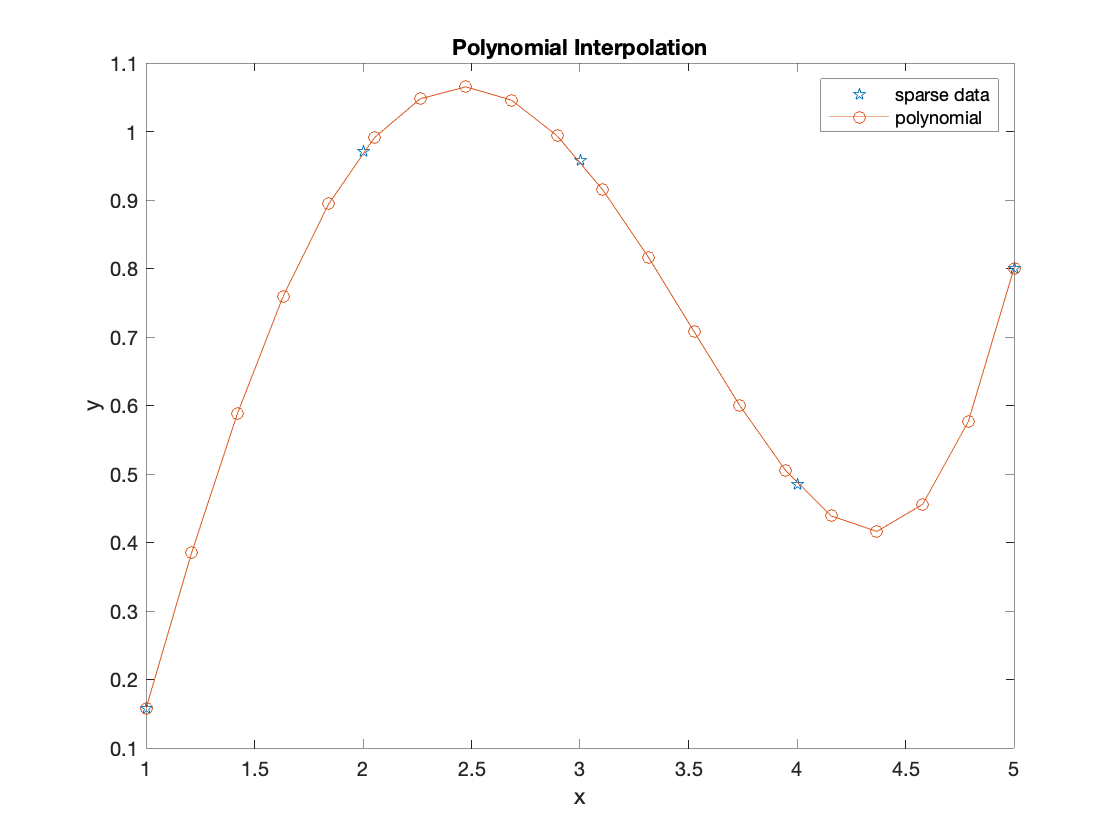

% MATLAB does not have a native polynomial interpolation so we will need to
% create one

% PN: For large arrays it can be beneficial to preallocate the space first,
% that is create an empty array of the size it will eventually grow to in a
% loop. It can make things much faster in the end. 

% We will create two matrices, one for inverting to determine the
% interpolation coefficients (A) and one for evaluating the polynomial for
% interpolation (B).
A = zeros([Np,Np]);
B = zeros([length(xi),Np]);

A(:,1) = ones(size(x));
B(:,1) = ones(size(xi));
for i = 2:Np
    A(:,i) = x.^(i-1);
    B(:,i) = xi.^(i-1);
end

% determine polynomial coefficients
m = inv(A)*y;

% compute interpolated values
yp = B*m;

figure;
plot(x,y,'p');      % sparce initial data
hold on;
plot(xi,yp,'o-');   % polynomial interpolated points
title('Polynomial Interpolation');
legend('sparse data','polynomial')
xlabel('x');
ylabel('y');

set(gca,'Box','on');

### 10.1.4 Cubic Spline

A spline is a polynomial interpolation method that is a little different.  Rather than using a single high order polynomial equation—expensive to compute for a large dataset—we can use a low order polynomial (typically a cubic) to interpolate between every pair of points.  This construction requires multiple piecewise polynomial, a spline, 

$s(x) = \begin{cases} p_0(x) & x_0 \leq x \leq x_1 \\ p_1(x) & x_1 \leq x \leq x_2 \\ \vdots \\ p_{N}(x) & x_{N} \leq x \leq x_{N+1} \\ \end{cases}$.

We add two constraints to the spline. First, the function must be continuous and pass through the observed points (i.e., the end points of each segment must join),

$p_i(x_{i}) = p_{i+1}(x_{i}) = y_i$.

Second, the function must be smooth, i.e., must have the same derivative of order $m$ at the joins, where the order of $m+1$ is the order of the spline.  For a cubic spline, $m = 2$,


$$p_i^{(2)}(x_{i}) = p_{i+1}^{(2)}(x_i)$$


This condition ensures uniqueness.  We will also assume the second derivative at the extremal points are zero for simplicity, i.e., $p_0^{(2)}(x_0) = 0$ and $p_N^{(2)}(x_{N+1}) = 0$.

  The $x$ coordinate is somewhat irrelevant for defining the spline segment so we define a variable $t \in [0,1]$ such that $x_i \to 0$ and $x_{i+1} \to 1$, thus for an interpolation point $x_k$ such that $x_i \leq x_k \leq x_{i+1}$, $t_k = (x_k - x_i)/(x_{i+1} - x_i)$.  Note it is possible to formulate the problem using $x$ but it is much simpler to formulate with $t$.  The $i$-th spline segment is then given by

$y_i(t) = a_i + b_i t + c_i t^2 + d_i t^3$,

where $i = {1,2,\ldots,N-1}$.  The endpoints have values, 

$y_i(0) = a_i$ and $y_i(1) = a_i + b_i + c_i + d_i$,

with derivatives

$\left.\frac{dy_i}{dt}\right|_{t=0} = D_i = b_i$ and $\left.\frac{dy_i}{dt}\right|_{t=1} = D_{i+1} = b_i + 2 c_i + 3 d_i$ .

Solving for the polynomial coefficients yields


$$\begin{array}{rcl} a_i &=& y_i \\ b_i &=& D_i \\ c_i &=& 3(y_{i+1} - y_i) - 2 D_i - D_{i+1} \\ d_i &=& 2(y_i - y_{i+1}) + D_i + D_i+1 \end{array}$$


Using these equations for the coefficients for each segment and the constraints we placed on the endpoints above, we can produce a tridiagonal set of equations,


$$\pmatrix{2 & 1 & 0 & 0 & 0 & \cdots & 0 & 0 & 0 \cr 1 & 4 & 1 & 0 & 0 & \cdots & 0 & 0 & 0 \cr 0 & 1 & 4 & 1 & 0 & \cdots & 0 & 0 & 0 \cr 0 & 0 & 1 & 4 & 1 & \cdots & 0 & 0 & 0 \cr \vdots & \vdots & \ddots & \ddots & \ddots & \cdots & \ddots & \ddots & \ddots \cr 0 & 0 & 0 & 0 & 0 & \cdots & 1 & 4 & 1 \cr 0 & 0 & 0 & 0 & 0 & \cdots & 0 &1 & 2} \pmatrix{D_0 \cr D_1 \cr D_2 \cr \vdots \cr D_{N-1} \cr D_N} = \pmatrix{3(y_1 - y_0) \cr 3(y_2 - y_0) \cr 3(y_3 - y_1) \cr \vdots \cr 3(y_{N-1} - y_{N-3}) \cr 3(y_{N} - y_{N-2})  \cr 3(y_{0} - y_{N-1})}$$


There is an efficient solver for these types of matrices that does not require inverting the matrix to determine the derivative values, $D_0 \ldots D_N$, which are then put back into the coefficient equations to determine the coefficients for each segment that are used interpolate to the desired locations.

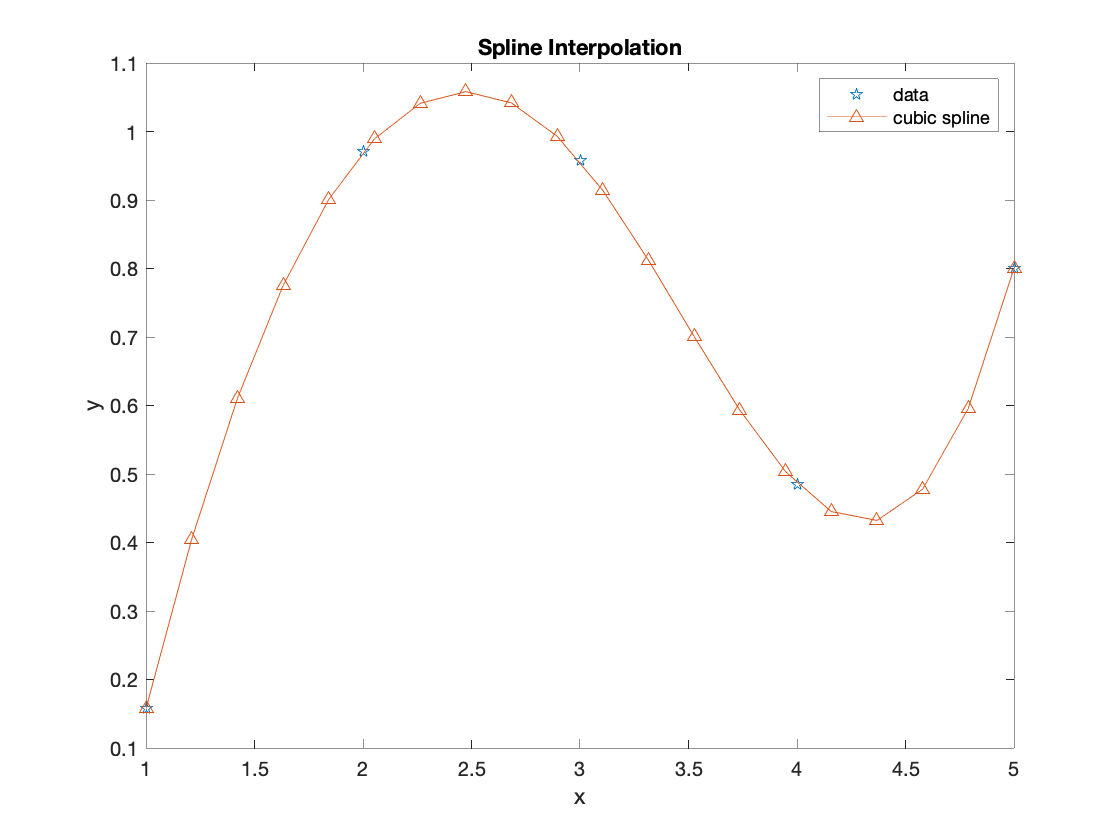

% interpolate using cubic spline (spine)
ycs = interp1(x,y,xi,'spline');

figure;
plot(x,y,'p');      % sparce initial data
hold on;
plot(xi,ycs,'^-');  % spline inerpolated data
title('Spline Interpolation');
legend('data','cubic spline')
xlabel('x');
ylabel('y');

set(gca,'Box','on');


clear all;

% Let's look at one last comparison taking a smoother function rather than
% a random one for interpolation.  We'll create a Gaussian and fit that
% using the various methods to see how each perform.
Np = 10;
x = [-4:4]';
y = gaussian(x,0,1);

xi = linspace(min(x),max(x),50)';
yt = gaussian(xi,0,1);              % true gaussian
yl = interp1(x,y,xi,'linear');      % linear interpolation
yp = polyinterp1(x,y,xi);           % polynomial interpolation
ycs = interp1(x,y,xi,'spline');     % cubic spline interpolation

% table of errors
t(1).method = 'linear';
t(1).error = sqrt(sum((yt - yl).^2)/length(xi));
t(2).method = 'polynomial';
t(2).error = sqrt(sum((yt - yp).^2)/length(xi));
t(3).method = 'cubic spline';
t(3).error = sqrt(sum((yt - ycs).^2)/length(xi));

t = struct2table(t)

t = 3×2 table
         method           error  
    ________________    _________

    {'linear'      }     0.013879
    {'polynomial'  }     0.030853
    {'cubic spline'}    0.0028627


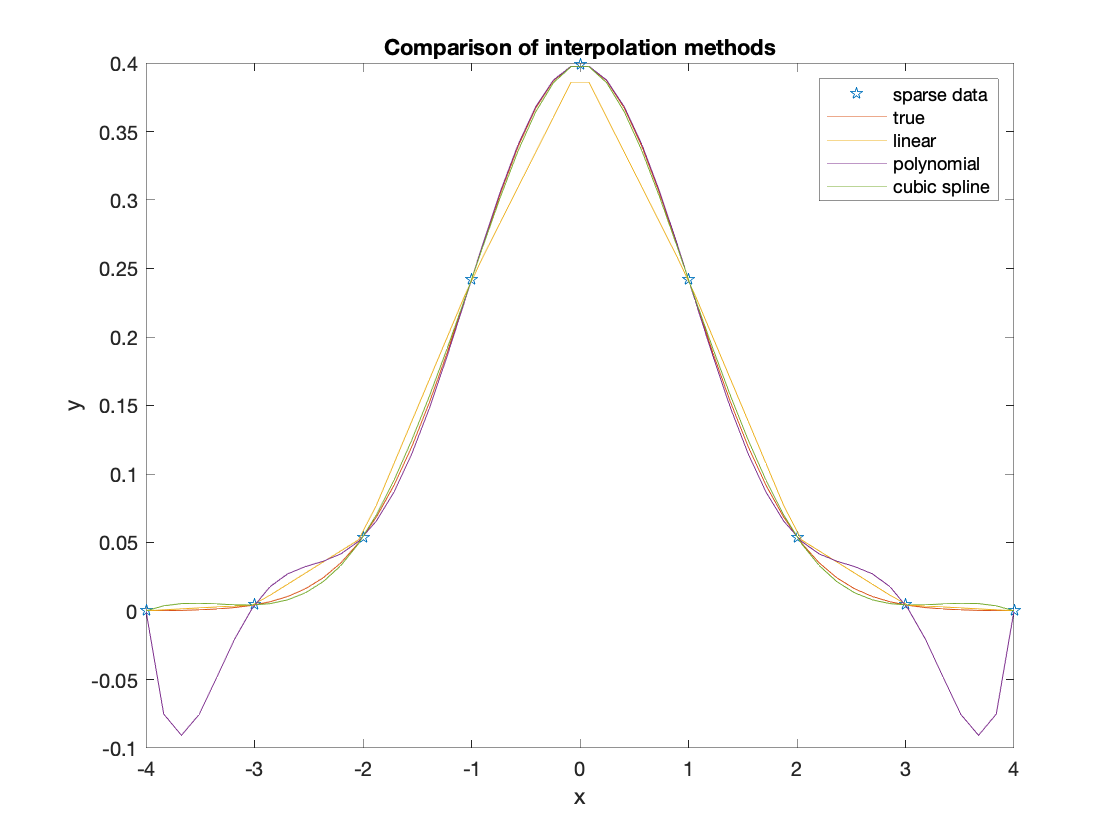

figure;
hold on;
plot(x,y,'p');      % gaussian points used for interpolation   
plot(xi,yt,'-');    % gaussian computed at interpolated points
plot(xi,yl,'-');    % linear
plot(xi,yp,'-');    % polynomial
plot(xi,ycs,'-');   % cubic spline

legend('sparse data','true','linear','polynomial','cubic spline');
xlabel('x');
ylabel('y');
title('Comparison of interpolation methods');
set(gca,'Box','on');

Polynomial interpolation does not perform well.  It tends to overfit, causing wild swings in the function between control points when compared with the other methods.  That is probably why MATLAB does not even include it as an option in its interpolation algorithm.  MATLAB does include a few additional methods that are not covered here and have their own advantages and disadvantages.  So when you interpolate, make sure that the type of interpolation you are using is reasonable given the likely behavior of the data between the observations.  

## 10.2 Extrapolation

Extrapolation should always be done with *extreme caution*, especially when the functions used to extrapolate are higher order polynomials because they are unconstrained and have a tendency to be out of control. Even spline and linear can be poorly behaved beyond the end points.  Look at it this way, there are three directions the true result may move relative to the end point value, up, down or stay constant, resulting in a 1/3 chance of getting the trajectory of the extrapolated data correct.

Let's see how it behaves for our previous random data and Gaussian.  If you run the code a few times on the random dataset, you will find that there are times the data are monotonically increasing or decreasing and yet the polynomial and spline go the opposite direction.  I realize that these datasets that we are creating are random; however, you would probably intuitively expect that if data are monotonic, that the extrapolated point would continue the trend.

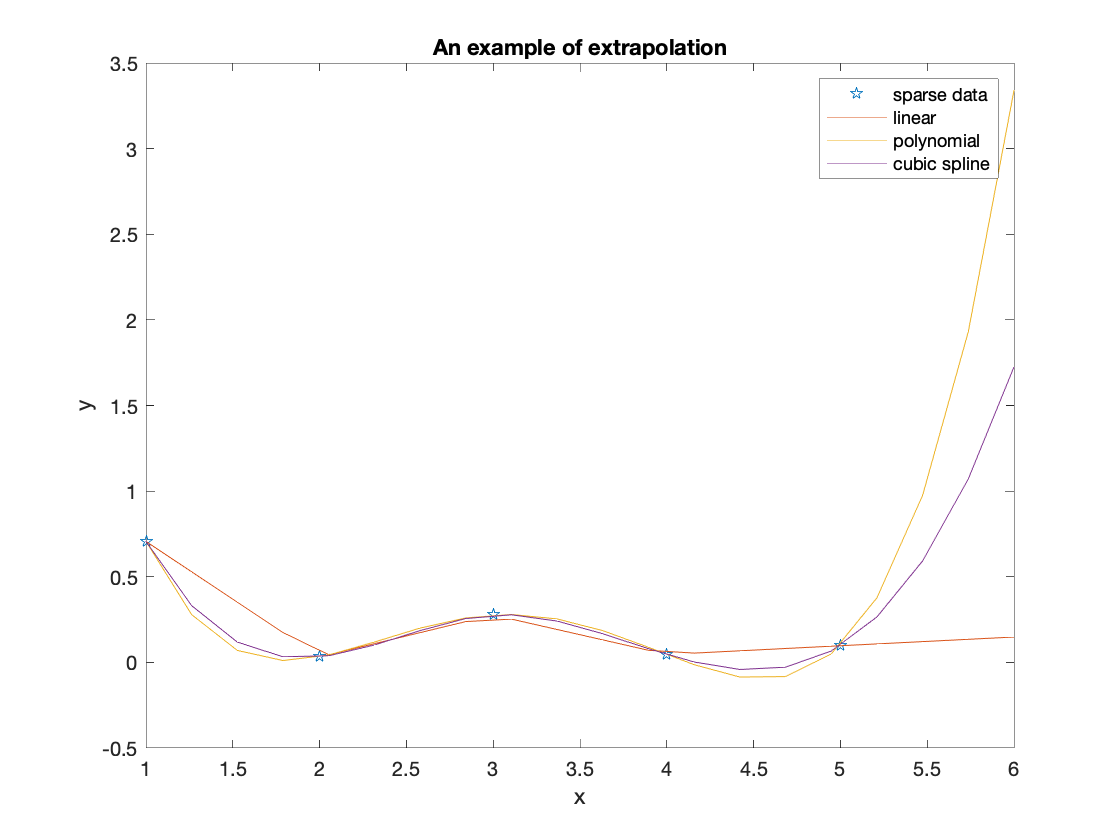

clear all;

%Let's create a random dataset with a few points
Np = 5;

x = [1:5]';
y = rand([Np 1]);

% Now let's create a set of location to interpolate and extrapolate
xi = linspace(min(x),max(x)+1,20)';

% interpolate
yp = polyinterp1(x,y,xi);
yi = interp1(x,y,xi,'linear','extrap');
ycs = interp1(x,y,xi,'spline','extrap');

% plot results
figure;
plot(x,y,'p');      % sparse data
hold on;
plot(xi,yi,'-');    % linear extrapolation
plot(xi,yp,'-');    % polynomial extrapolation
plot(xi,ycs,'-');   % spline extrapolation

title('An example of extrapolation');
legend('sparse data','linear','polynomial','cubic spline')
xlabel('x');
ylabel('y');

set(gca,'Box','on');


Let's examine the extrapolation again using a Gaussian.

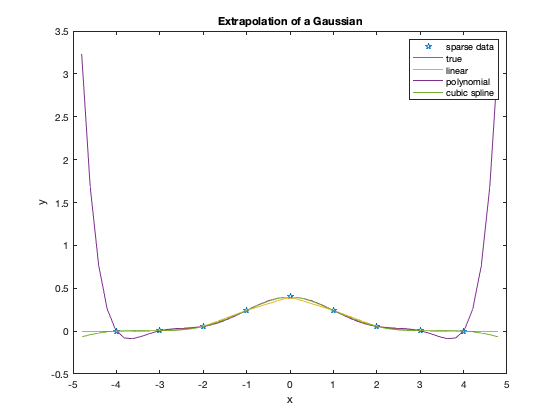

clear all;
% Let's look at the interpolation of a Gaussian again, but now extrapolate
% as well
Np = 10;
x = [-4:4]';
y = gaussian(x,0,1);

% Now let's create a set of location to interpolate and extrapolate
xi = linspace(min(x)-(max(x) - min(x))/10,max(x)+(max(x) - min(x))/10,50)';

% interpolate
yt = gaussian(xi,0,1);              % true
yi = interp1(x,y,xi,'linear');      % linear
yp = polyinterp1(x,y,xi);           % polynomial
ycs = interp1(x,y,xi,'spline');     % cubic spline

% plot results
figure;
hold on;
plot(x,y,'p');      % sparse gaussian points
plot(xi,yt,'-');    % true
plot(xi,yi,'-');    % linear
plot(xi,yp,'-');    % polynomial
plot(xi,ycs,'-');   % cubic spline

legend('sparse data','true','linear','polynomial','cubic spline');
xlabel('x');
ylabel('y');
title('Extrapolation of a Gaussian');
set(gca,'Box','on');

## 10.3 Two-dimensional Interpolation

Many observables vary in multiple dimensions as a function of position, state variables, or some other set of independent variables. Below is a table that gives several examples of datasets that vary in two or three dimensions.


$$\begin{array}{lcl} \bf \text{field or observable} & & \bf \text{dimensions} \\ \text{elevation} & & \text{latitude, longitude} \\ \text{gravity} & & \text{latitude, longitude} \\ \text{mineral modes} & & \text{pressure, temperature, composition} \\ \text{lake water H, O isotopes} & & \text{temperature, humidity} \end{array}$$


When analyzing such data, we often need to interpolate the data to a regular grid for interpretation or to specific points for required for models or interrogation.  For all the 1-D interpolation methods, there are equivalent 2-D methods.  I won't get into how to change these methods change for 2-D applications, but the concepts are very similar.  One thing that is common among many of the methods—at least the way they are coded in many functions—require data to be located on a regular grid.  We'll first cover how to interpolate with irregular data and then cover how to grid data prior to interpolation.

### 10.3.1 Interpolating with scattered data

If we are interested in estimating the values at a set of points that are not on a regular grid the intermediate step of gridding has the potential of creating additional uncertainty.  In those cases we want to interpolate directly from data that are not regularly gridded.  The example of the interpolation below is provided by MATLAB, though I've slightly modified it and added an explanation of how it works.  To start we need to create a set of observations, which we will do from the 2-D function,


$$v(x,y) = \sin^4(x) + \cos^4(y)$$


This is not a geologically realistic field, but it illustrates the method nicely.  The true function and our random set of observations are shown in the figure below.

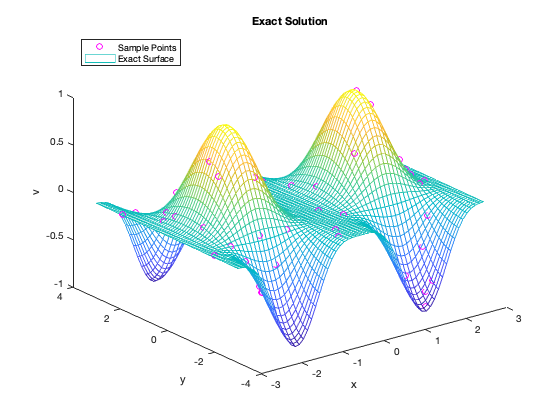

clear all;
% this example comes from MATLAB (slightly modified)

% create a regular spatial grid
[xq,yq] = meshgrid(-3:0.1:3);

% compute values of a periodic function in x and y
vtrue = sin(xq).^4 .* cos(yq);

% randomly sample 50 points from the periodic function
x = -3 + 6*rand(50,1);
y = -3 + 6*rand(50,1);
v = sin(x).^4 .* cos(y);

% plot the true grid and random points
figure;
plot3(x,y,v,'mo');
hold on;
mesh(xq,yq,vtrue);

title('Exact Solution');
legend('Sample Points','Exact Surface','Location','NorthWest');
xlabel('x');
ylabel('y');
zlabel('v');

To interpolate the set of observations to a desired set of points, we need to know the region of influence attributable to each control point.  To do that we need to create a set of polygons that surround each of the control points such that the control point contained within the polygon is the closest observation to all other points within.  Another way to look at it is that the polygon edges represent the lines where the two control points on either side are exactly equal in distance to the bounding line.  We can illustrate the result using a Voronoi diagram.

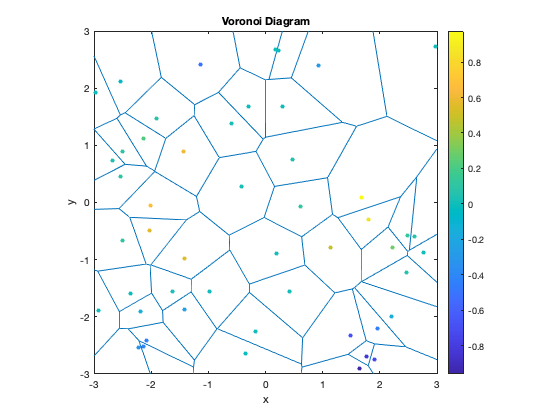

% plot the voronoi polygons used for interpolation 
figure;
voronoi(x,y);
hold on;
scatter(x,y,20,v,'filled');
colorbar;
xlabel('x');
ylabel('y');
title('Voronoi Diagram');
axis([-3 3 -3 3]);
axis square;

The nearest neighbor interpolation assigns the value of the control point to all points within the polygon.  The linear interpolation creates a plane defined by the nearest three points assigning a value of the plane to the desired point (so it uses triangulation rather than the Voronoi polygons).  The natural neighbor scheme creates a bounding polygon with for desired interpolation point with respect to the nearest set of control points.  It then uses the percentage of each control polygon contained within the bounding polygon to weight the influence of each of the surrounding points on the estimated value.  The result is a smooth interpolation.  The result of all three methods are shown below.

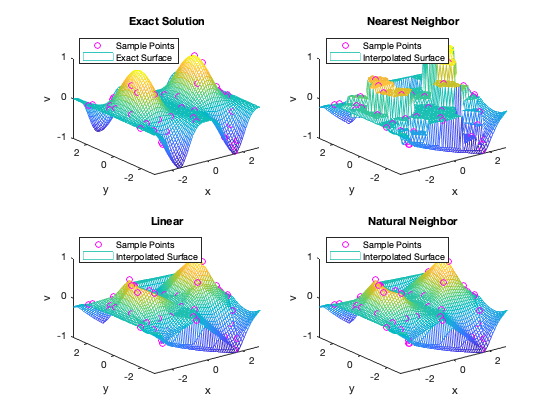

% true solution
figure;
subplot(221);
plot3(x,y,v,'mo')
hold on
mesh(xq,yq,vtrue)
title('Exact Solution')
legend('Sample Points','Exact Surface','Location','NorthWest')
xlabel('x');
ylabel('y');
zlabel('v');

% use scatteredInterpolant() to create a function that will interpolate to
% our desired locations.  Note scatteredInterpolant() does not interpolate,
% it creates a function that interpolates based on our control points
F = scatteredInterpolant(x,y,v);

% use nearest neighbor interpolation scheme
F.Method = 'nearest';
vq1 = F(xq,yq);

subplot(222);
plot3(x,y,v,'mo')
hold on
mesh(xq,yq,vq1)
title('Nearest Neighbor')
legend('Sample Points','Interpolated Surface','Location','NorthWest')
xlabel('x');
ylabel('y');
zlabel('v');

% use linear interpolation scheme
F.Method = 'linear';
vq2 = F(xq,yq);

subplot(223);
plot3(x,y,v,'mo')
hold on
mesh(xq,yq,vq2)
title('Linear')
legend('Sample Points','Interpolated Surface','Location','NorthWest')
xlabel('x');
ylabel('y');
zlabel('v');

% use natural (smooth) interpolation scheme
F.Method = 'natural';
vq3 = F(xq,yq);

subplot(224);
plot3(x,y,v,'mo')
hold on
mesh(xq,yq,vq3)
title('Natural Neighbor')
legend('Sample Points','Interpolated Surface','Location','NorthWest')
xlabel('x');
ylabel('y');
zlabel('v');

Although I've shown these on a mesh plots above, these perspective plots can be difficult to interpret.  It is better to display the results as contour or pcolor plots which are 2-D plots with color to indicate the third dimension.

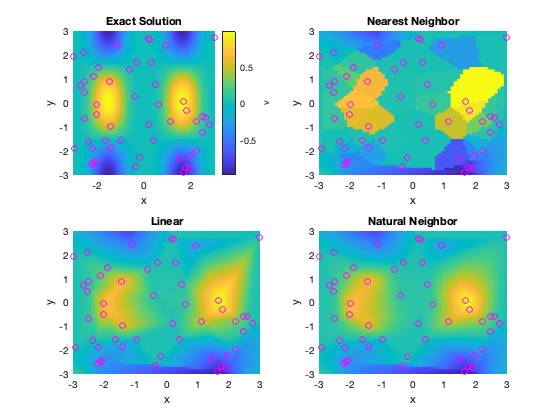

% true solution
figure;
subplot(221);
pcolor(xq,yq,vtrue)
shading flat;
hold on
plot(x,y,'mo')
title('Exact Solution')
cb = colorbar;
cb.Label.String = 'v';
xlabel('x');
ylabel('y');

subplot(222);
pcolor(xq,yq,vq1)
shading flat;
hold on
plot(x,y,'mo')
title('Nearest Neighbor')
xlabel('x');
ylabel('y');

subplot(223);
pcolor(xq,yq,vq2)
shading flat;
hold on
plot(x,y,'mo')
title('Linear')
xlabel('x');
ylabel('y');

subplot(224);
pcolor(xq,yq,vq3)
shading flat;
hold on
plot(x,y,'mo')
title('Natural Neighbor')
xlabel('x');
ylabel('y');

### 10.3.2 Gridding

So we basically created an interpolated grid in the previous section using scatteredInterpolant(), though MATLAB has a slightly easier version called griddata() that removes the step of creating the interpolation function and includes an additional cubic interpolation method.

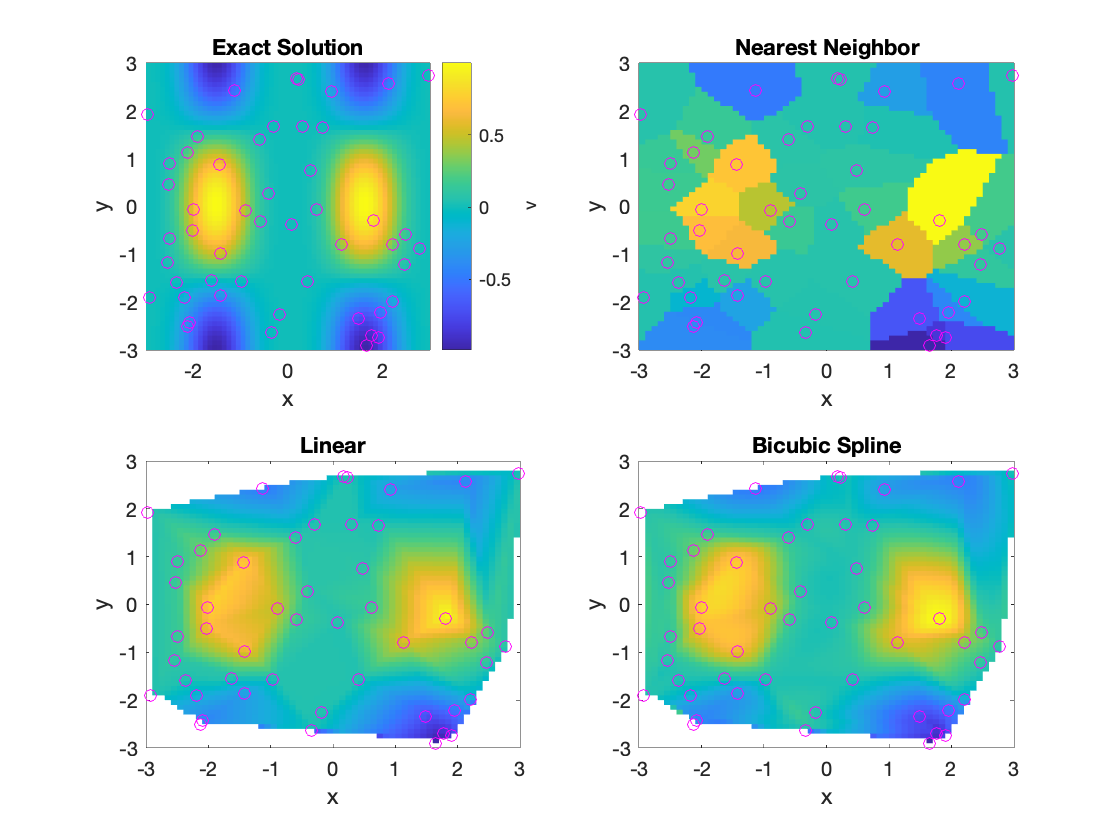

vq1 = griddata(x,y,v,xq,yq,'nearest');
vq2 = griddata(x,y,v,xq,yq,'linear');
vq3 = griddata(x,y,v,xq,yq,'cubic');

figure;
subplot(221);
pcolor(xq,yq,vtrue)
shading flat;
hold on
plot(x,y,'mo')
title('Exact Solution')
cb = colorbar;
cb.Label.String = 'v';
xlabel('x');
ylabel('y');

subplot(222);
pcolor(xq,yq,vq1)
shading flat;
hold on
plot(x,y,'mo')
title('Nearest Neighbor')
xlabel('x');
ylabel('y');

subplot(223);
pcolor(xq,yq,vq2)
shading flat;
hold on
plot(x,y,'mo')
title('Linear')
xlabel('x');
ylabel('y');

subplot(224);
pcolor(xq,yq,vq3)
shading flat;
hold on
plot(x,y,'mo')
title('Bicubic Spline')
xlabel('x');
ylabel('y');

### 10.3.3 Mosaic Grids

One of the challenges in dealing with spatial data is that grid positions and grid resolutions can differ.  Add to this difference, there can be a difference bias between the two datasets that will need to be reconciled.

- Choose a suture line.

- Examine the differences.  Compute the average of each dataset along the suture.  You can raise one, lower the other, or adjust both two the mean.

- When the differences in resolution (or values) is large, smoothing of the datasets may be necessary.

### 10.3.3 Variograms

#### 10.3.3.1 Nugget, sill and range

Variograms, or sometimes semi-variograms, are a measure of the spatial variance of a dataset with respect to distance between points.  They are the first step to producing a smarter spatial interpolation.  The general idea is that a spatially variable dataset will generally exhibit correlation between points when they are nearby and virtually no correlation as when the spatial scales are large.  This concept makes some sense.  Pick an outcrop and measure its chemistry.  If you pick another outcrop nearby, it is probably the same rock type and therefore will have a very similar chemistry.  As you get further away from the original outcrop you may find yourself in the same terrane and while there will be some correlation with the initial outcrop, there may be less because they are different rock types.  The further you go from the original outcrop the less likely you are to be in the same terrane and the less likely the data will correlate at all.

A variogram is described by three parameters, the ***nugget***, ***sill*** and ***range***.  The *nugget* refers to the samples at the closest distance, generally with lowest variance, highest spatial correlation.  The *sill* represents the average variance for samples separated by large distances, lowest spatial correlation between samples.  The *range* is scale factor with units of distance at which the spatial variance approaches the sill variance. 

An example is provided in the figure below.  Note that for this variogram model, the range indicates where the variance reaches the sill, however, for most idealized variogram models the range does not correspond to this exact point, but rather a defined point on the variogram.

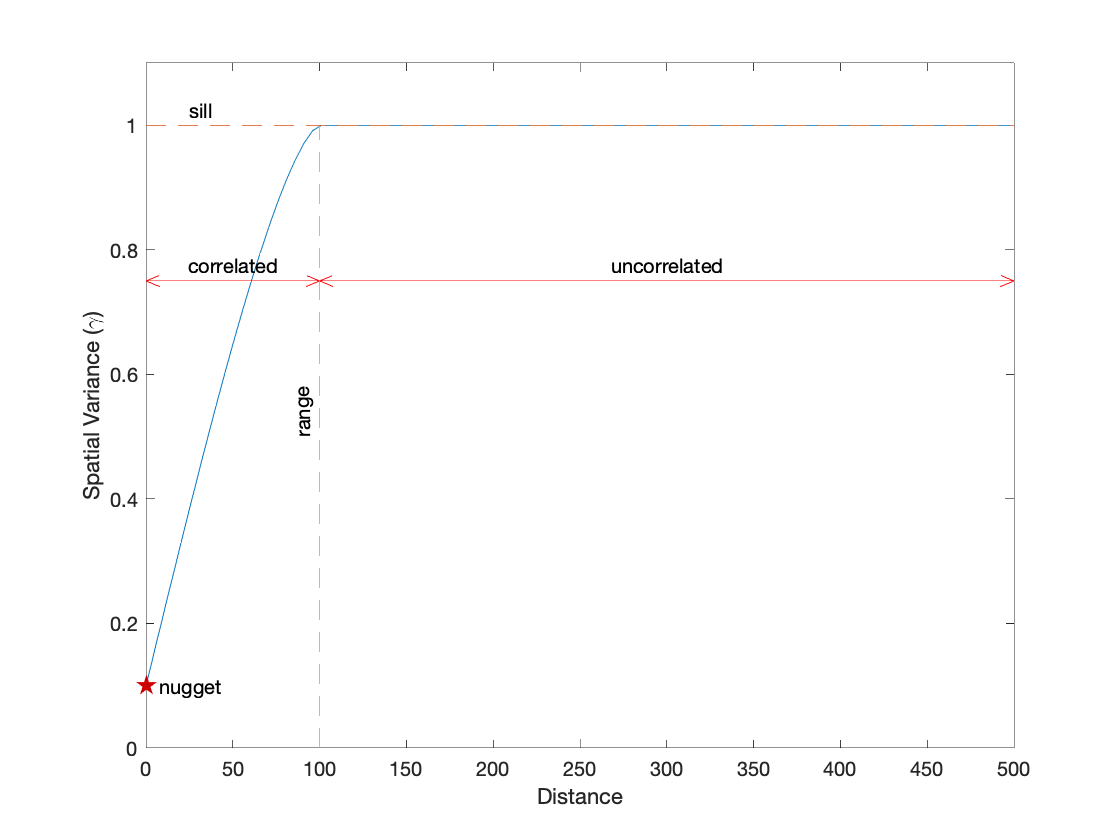

% a simple variogram, illustrating the nugget, sill and range
clear all;

% define nugget, sill and range
nugget = 0.1;
sill = 1;
range = 100;

% compute a circular variogram model
[h,gamma] = variogram_model(nugget,sill,range,'circular');

figure;
hold on;
plot(h,gamma);
axis([0 h(end) 0 1.1*sill]);
arrow([0 range],0.75*[sill sill],'style','double','color','r');
text(0.5*range,0.775*sill,'correlated','HorizontalAlignment','center');
arrow([range h(end)],0.75*[sill sill],'style','double','color','r');
text(0.5*(h(end)-range)+range,0.775*sill,'uncorrelated','HorizontalAlignment','center');

% plot nugget
scatter(0,nugget,120,[0.8 0 0],'p','filled');
text(0.075*range,nugget,'nugget');
% plot sill
plot([0 h(end)],sill*[1 1],'--');
text(0.25*range,1.025*sill,'sill');
% plot range
plot([range range],[0 sill],'--');
text(0.9*range,0.5*sill,'range','Rotation',90)
xlabel('Distance');
ylabel('Spatial Variance (\gamma)');
set(gca,'Box','on');

#### 10.3.3.2 Computing variograms

Suppose we collect a set of observations, $V = \{v_0(x_0,y_0),v_1(x_1,y_1),\ldots,v_{N+1}(x_{N+1},y_{N+1})\}$, where $(x_i,y_i)$ is the spatial location of the $i$-th sample with a value of $v_i$.  The location can both be horizontal or horizontal and vertical.  The distance between any two points $i$ and $j$ is given by the Euclidian distance $d_{ij} = ((x_j - x_i)^2 - (y_j - y_i)^2)^{1/2}$.  The variogram is computed at a set of distances (lags) with edges, $H = \{h_0,h_1,\ldots,h_{M+1}\}$, with the spatial variance, $\gamma_k$, between a lag $h_k$ and $h_{k+1}$, where $k = 0,\ldots,M$,


$$\gamma(h_k,h_{k+1}) = \frac{1}{2 N_k} \sum_{i = 0}^{N} \sum_{j = i+1}^{N+1} \begin{cases} (v_j - v_i)^2, & h_k \leq d_{ij} \leq h_{k+1} \\ 0, & \text{otherwise} \end{cases}$$


where $N_k$ is the number of data with distance $h_k < d < h_{k+1}$, or more formally,


$$N_k = \sum_{i = 0}^{N} \sum_{j = i+1}^{N+1} \begin{cases} 1, & h_k < d_{ij} < h_{k+1} \\ 0, & \text{otherwise} \end{cases}$$


Variograms can have difficulty with non-Gaussian distributed data.  If a data set is skewed, it may be necessary to transform the data to a Gaussian form for computing the variogram and transformed back afterward.  For many geochemical data, simply taking the $\log$ of the data is sufficient, though for some datasets a transformation can be performed using a Q-Q plot (see Section 5.3.2).

Let's look at an example using heat production data for granites of Australia (map below).

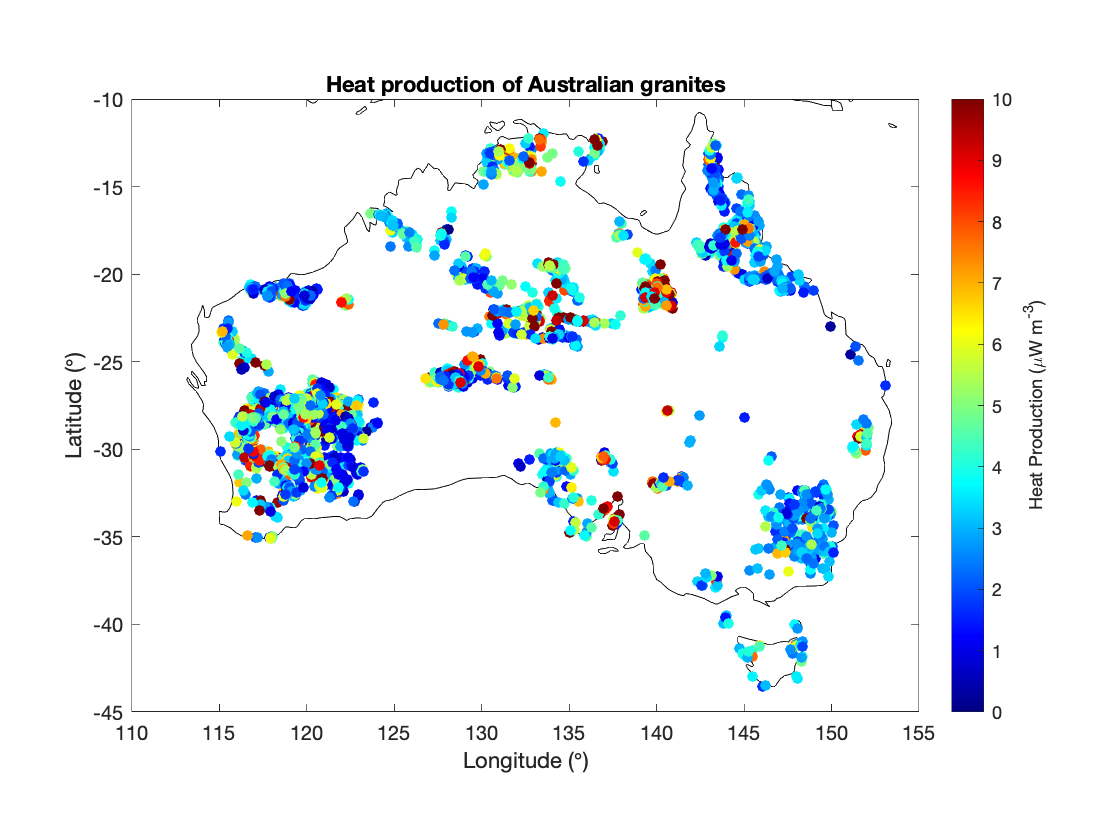

clear all;

% load Australian heat production dataset
data = readtable('australian_hp.csv','Format','%s%f%f%f');
% PN: The format option/string pair may not be necessary for you... I just
% can't get my machines to work without it.  The %s indicates a text field
% and the %f indicate a decimal number (a.k.a. float) field.

% filter to find only granites
% (and add geographic bounds to remove some stray points)
ind = strcmp(data.rock_type,'granite') & -45 < data.latitude & data.latitude < -10 & 110 < data.longitude & data.longitude < 155;

% make our dataset contain only the granites (otherwise it is quite large)
data = data(ind,:);

figure;
plotcoast;
hold on;
% PN: MATLAB has a mapping toolbox for creating maps (it just sucks...slow
% and takes up a LOT of memory) so I usually just plot in geographic
% coordinates in MATLAB and make my maps pretty someplace else.
scatter(data.longitude,data.latitude,30,data.heat_production,'filled');
colormap(jet);
cb = colorbar;
cb.Label.String = 'Heat Production (\muW m^{-3})';
caxis([0 10]);
xlabel('Longitude (\circ)');
ylabel('Latitude (\circ)')
title('Heat production of Australian granites');
axis([110 155 -45 -10]);

The distribution of the data are highly skewed to low values (long high tail) so we will need to transform the data which we will do by simply taking the log, which yields a reasonable approximation of a Gaussian distribution.

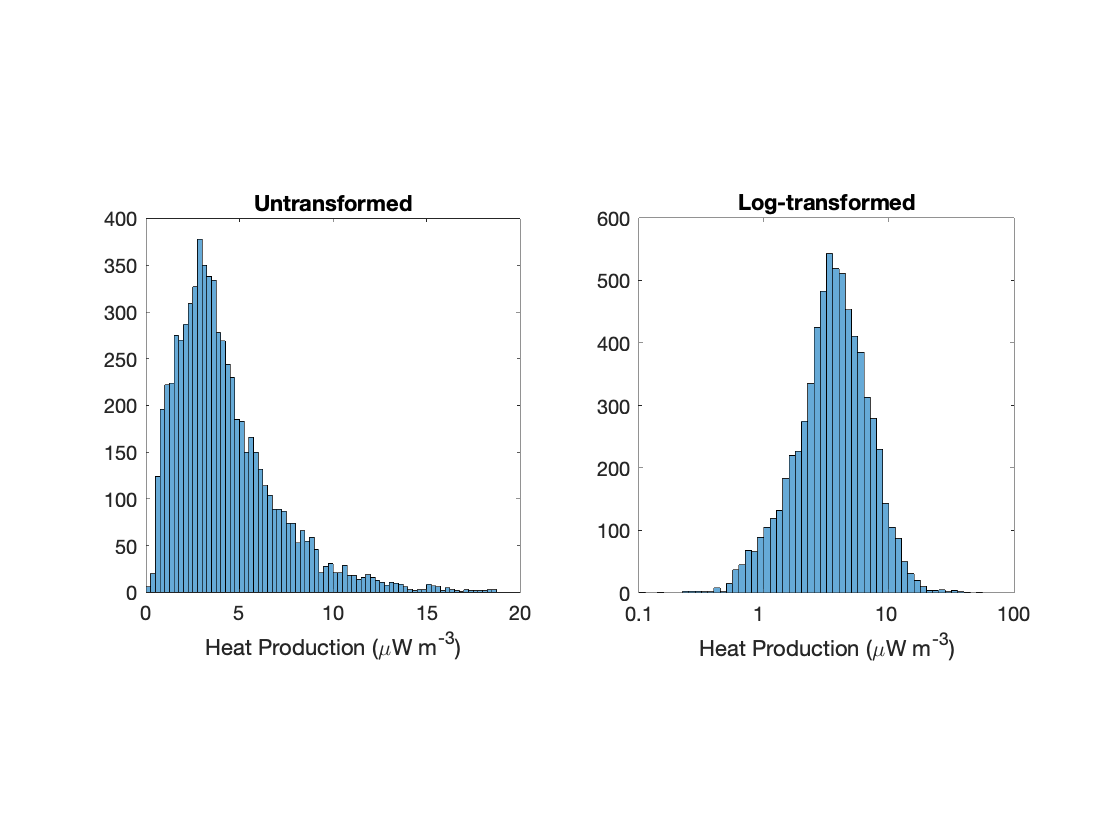

figure;
% linear space;
subplot(121);
histogram(data.heat_production,'BinWidth',0.25);
xlim([0 20]);
xlabel('Heat Production (\muW m^{-3})');
title('Untransformed');
axis square;

% log-space
subplot(122);
histogram(log10(data.heat_production));
set(gca,'XTick',[-1:2],'XTickLabel',10.^[-1:2]);
xlim([-1 2]);
xlabel('Heat Production (\muW m^{-3})');
title('Log-transformed');
axis square;

Now we can compute the variogram for the heat production data.

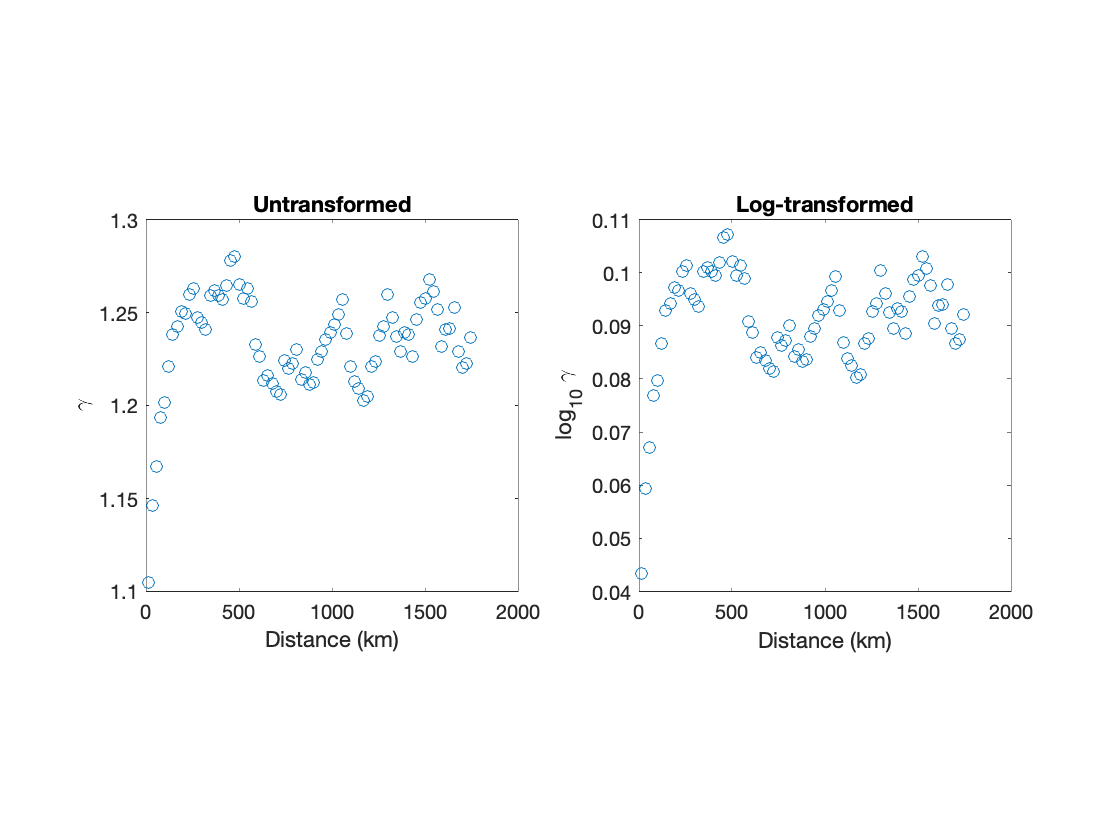

[r,gamma] = variogram(data.longitude,data.latitude,log10(data.heat_production),1);

figure;
% variogram of untransformed data
subplot(121);
plot(r,10.^gamma,'o');
hold on;
xlabel('Distance (km)');
ylabel('\gamma');
title('Untransformed');
axis square;

% variogram of log-transformed data
subplot(122);
plot(r,gamma,'o');
xlabel('Distance (km)');
ylabel('log_{10} \gamma');
title('Log-transformed');
axis square;

#### 10.3.3.3 Idealized variograms used for kriging

Once we have a variogram, we will need to determine the nugget, sill and range parameters.  To do so we will need to fit an idealized variogram to the data.  There are several models,

***Spherical***

For a nugget, $n$, sill, $s$, and range, $r$, a spherical model for spatial variance is given by


$$\gamma(h) = \begin{cases} n + (s - n)\left( \frac{3 h}{2 r} - \frac{h^3}{2 r^3} \right), & 0 < h \leq r \\ s, & h > r \end{cases}$$


***Circular***

The circular model for spatial variance is given by


$$\gamma(h) = \begin{cases} n + (s - n)\left[ 1 - \frac{2}{\pi}\cos^{-1} \left(\frac{h}{r}\right) + \frac{2h}{\pi r^2}(r^2 + h^2)^{1/2} \right], & 0 < h \leq r \\ s, & h > r \end{cases}$$


***Gaussian***

The Gaussian model for spatial variance is given by


$$\gamma(h) = n + (s - n)\left[1 - \exp \left( -\frac{h^2}{r^2} \right) \right]$$


***Exponential***

The gaussian model for spatial variance is given by


$$\gamma(h) = n + (s - n)\left[1 - \exp \left( -\frac{h}{r} \right) \right]$$


***Rational Quadratic***

The rational quadratic model for spatial variance is given by


$$\gamma(h) = n + (s - n)\left( \frac{h^2}{r^2 + h^2} \right)$$


***Wave***

The wave model for spatial variance is given by


$$\gamma(h) = n + (s - n)\left[1 - \frac{r}{h} \sin \left( \frac{h}{r} \right) \right]$$


Let's use each of these models to fit the untransformed variogram for heat production above.  To do so I have written a function for each one of these idealized models and performed a Newton's non-linear inversion (see Section 6.6.2.3) to find the best-fitting values of $h$.  To use Newton's method, I need a starting guess which I will estimate from the variogram above.  I choose a nugget of 1.1 $\mu$W m$^{-3}$, a sill of 1.25 $\mu$W m$^{-3}$ and a range of 200 km.

figure;
plot(r,10.^gamma,'o');
hold on;
xlabel('Distance');
ylabel('\gamma');
pbaspect([1.618 1 1]);

nugget = 1.1;
sill = 1.25;
range = 200;

% I'm going to limit the variogram fit to the first 600 km because of the
% variability in the variogram h > 600.  But I'll make an exception for the
% wave model which performs better using all of the variogram.
ind = r < 600;

% circular model
[nugget,sill,range,rms] = variogram_model(nugget,sill,range,'circular',r(ind),10.^gamma(ind));

  Starting Model:   0   RMS: 0.0133
  Iteration:        1   RMS: 0.0123
  Iteration:        2   RMS: 0.0102
  Iteration:        3   RMS: 0.0102
  Iteration:        4   RMS: 0.0102
  Iteration:        5   RMS: 0.0102
  Iteration:        6   RMS: 0.0102

  Variogram Model: circular
  Nugget: 1.107734
  Sill: 1.257153
  Range: 188.108474


[h,gc] = variogram_model(nugget,sill,range,'circular',r);
plot(h,gc,'-');

% spherical model
[nugget,sill,range,rms] = variogram_model(nugget,sill,range,'spherical',r(ind),10.^gamma(ind));

  Starting Model:   0   RMS: 0.0109
  Iteration:        1   RMS: 0.0100
  Iteration:        2   RMS: 0.0102
  Iteration:        2   RMS: 0.0100
  Iteration:        2   RMS: 0.0100
  Iteration:        3   RMS: 0.0102
  Iteration:        3   RMS: 0.0100
  Iteration:        3   RMS: 0.0100
  Iteration:        3   RMS: 0.0100
  Iteration:        3   RMS: 0.0100
  Iteration:        3   RMS: 0.0100
  Iteration:        3   RMS: 0.0100
  Iteration:        3   RMS: 0.0100



  Variogram Model: spherical
  Nugget: 1.107281
  Sill: 1.257330
  Range: 211.642664


[h,gs] = variogram_model(nugget,sill,range,'spherical',r);
plot(h,gs,'-');

% Gaussian model
[nugget,sill,range,rms] = variogram_model(nugget,sill,range,'gaussian',r(ind),10.^gamma(ind));

  Starting Model:   0   RMS: 0.0384
  Iteration:        1   RMS: 0.0152
  Iteration:        2   RMS: 0.0111
  Iteration:        3   RMS: 0.0107
  Iteration:        4   RMS: 0.0107
  Iteration:        5   RMS: 0.0107

  Variogram Model: gaussian
  Nugget: 1.121357
  Sill: 1.257199
  Range: 99.801987


[h,gg] = variogram_model(nugget,sill,range,'gaussian',r);
plot(h,gg,'-');

% exponential model
[nugget,sill,range,rms] = variogram_model(nugget,sill,range,'exponential',r(ind),10.^gamma(ind));

  Starting Model:   0   RMS: 0.0129
  Iteration:        1   RMS: 0.0104
  Iteration:        2   RMS: 0.0095
  Iteration:        3   RMS: 0.0095
  Iteration:        4   RMS: 0.0095

  Variogram Model: exponential
  Nugget: 1.080481
  Sill: 1.260707
  Range: 78.648382


[h,ge] = variogram_model(nugget,sill,range,'exponential',r);
plot(h,ge,'-');

% quadratic model
[nugget,sill,range,rms] = variogram_model(nugget,sill,range,'quadratic',r(ind),10.^gamma(ind));

  Starting Model:   0   RMS: 0.0164
  Iteration:        1   RMS: 0.0098
  Iteration:        2   RMS: 0.0098
  Iteration:        3   RMS: 0.0098

  Variogram Model: quadratic
  Nugget: 1.106966
  Sill: 1.263746
  Range: 69.904171


[h,gq] = variogram_model(nugget,sill,range,'quadratic',r);
plot(h,gq,'-');

% wave model
[nugget,sill,range,rms] = variogram_model(nugget,sill,range,'wave',r,10.^gamma);

  Starting Model:   0   RMS: 0.0368
  Iteration:        1   RMS: 0.0216
  Iteration:        2   RMS: 0.0215
  Iteration:        3   RMS: 0.0212
  Iteration:        4   RMS: 0.0206
  Iteration:        5   RMS: 0.0202
  Iteration:        6   RMS: 0.0197
  Iteration:        7   RMS: 0.0194
  Iteration:        8   RMS: 0.0194
  Iteration:        9   RMS: 0.0193
  Iteration:       10   RMS: 0.0193
  Iteration:       11   RMS: 0.0191
  Iteration:       12   RMS: 0.0184
  Iteration:       13   RMS: 0.0178
  Iteration:       14   RMS: 0.0179
  Iteration:       14   RMS: 0.0186
  Iteration:       14   RMS: 0.0176
  Iteration:       15   RMS: 0.0176
  Iteration:       16   RMS: 0.0176
  Iteration:       16   RMS: 0.0176
  Iteration:       16   RMS: 0.0176
  Iteration:       17   RMS: 0.0176

  Variogram Model: wave
  Nugget: 1.129328
  Sill: 1.237461
  Range: 43.626490


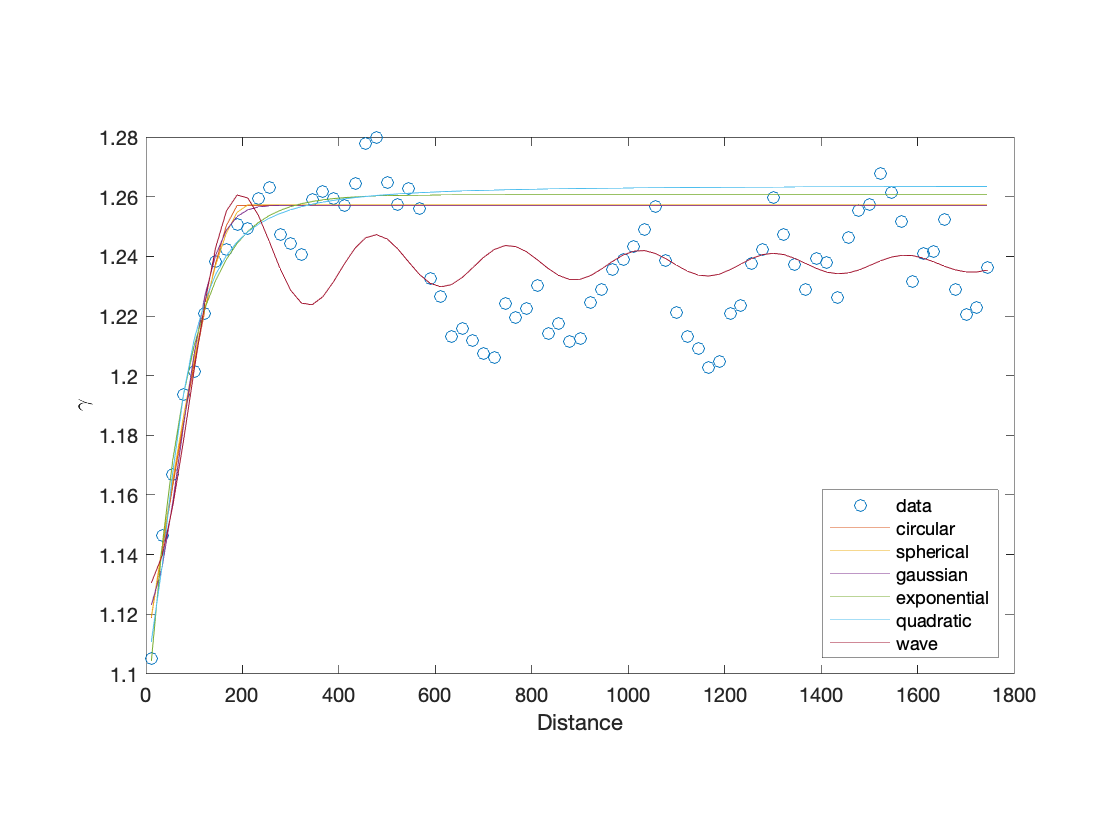

[h,gq] = variogram_model(nugget,sill,range,'wave',r);
plot(h,gq,'-');

legend('data','circular','spherical','gaussian','exponential','quadratic','wave','Location','southeast');

Which one is best? You be the judge. In some ways, I think the wave model performs best, although I would probably be more apt to choose the exponential model (you may have to zoom in to see why).

#### 10.3.3.4 Direction Variograms

If you look closely at the Australian heat production data (e.g. Yilgarn Craton in Western Australia), you will find that there are regions where heat production appears to change a lot more east–west than north–south or vice versa.  This anisotropy in the data is a reflects the orientation of terranes that amalgamation these portions of Australia.  This variability may be partly or fully the source of the periodic variations that can be seen in the variogram.  One possible way to explore these variations is to compute variograms directionally, which is to say compute variograms by restricting $\gamma$ between the angles $\theta$ and $\theta + \alpha$ of each point, $(x_i,y_i)$.  One potential issue arises if we take directional variograms, if we restrict to an angle, when we are far from $(x_i,y_i)$, the area contained within each sector is large and may average too much data orthogonal to the average radial vector from each point, averaging out the anisotropy effect.  To correct for this, we can restrict the width of the sector by a fixed bandwidth.

### 10.3.4 Kriging

Kriging is a form of spatial interpolation that uses a variogram to help inform a set of weights applied to the data when estimating the value at an unobserved point.  Kriging can be performed in one dimension or multiple dimensions and is known to statisticians as Gaussian process regression (of course they couldn't let it be named after a geoscientist), although the method in geostatistics is named after a geologist Danie Krige who first developed the method to interpolate geochemical data.  The value estimated at an unobserved point $(u,v)$ is determined by a mean of the observation points weighted by their proximity to $(u,v)$.  The 

## 10.4 Producing Profiles

Producing a profile from a dataset is a projection problem.  Values are either interpolated to the profile or points are projected to a profile line along a line orthogonal to the profile.  However, the end result you are attempting to achieve may require different methods to interpolate or project.

### 10.4.1 Projecting Irregularly Spaced Data

The problem of placing irregularly spaced data onto an arbitrary profile is a projection problem.  Points must be projected to a line.

The unknown projection of $(x_i,y_i)$ on to the profile, is defined by the intersection of the profile, $y = m x + b$, and an orthogonal line, slope $-m^{-1}$, which passes through $(x_i,y_i)$.  The unknown projected point, $(\hat{x}_i, \hat{y}_i)$, can be determined from the equation for the projection

$\hat{y}_i - y_i = -m^{-1}(\hat{x}_i - x_i)$,

and the profile

$\hat{y}_i = m \hat{x}_i + b$.

Inserting the latter equation into the former, we can solve for $\hat{x}_i$ and then back into the latter to find $\hat{y}_i$,


$$\begin{array}{lcl} \hat{x}_i & = & \frac{x + m(y - b)}{m^2 + 1} \\ \hat{y}_i & = & \frac{m^2y_i + m x_i + b}{m^2 + 1} \end{array}$$


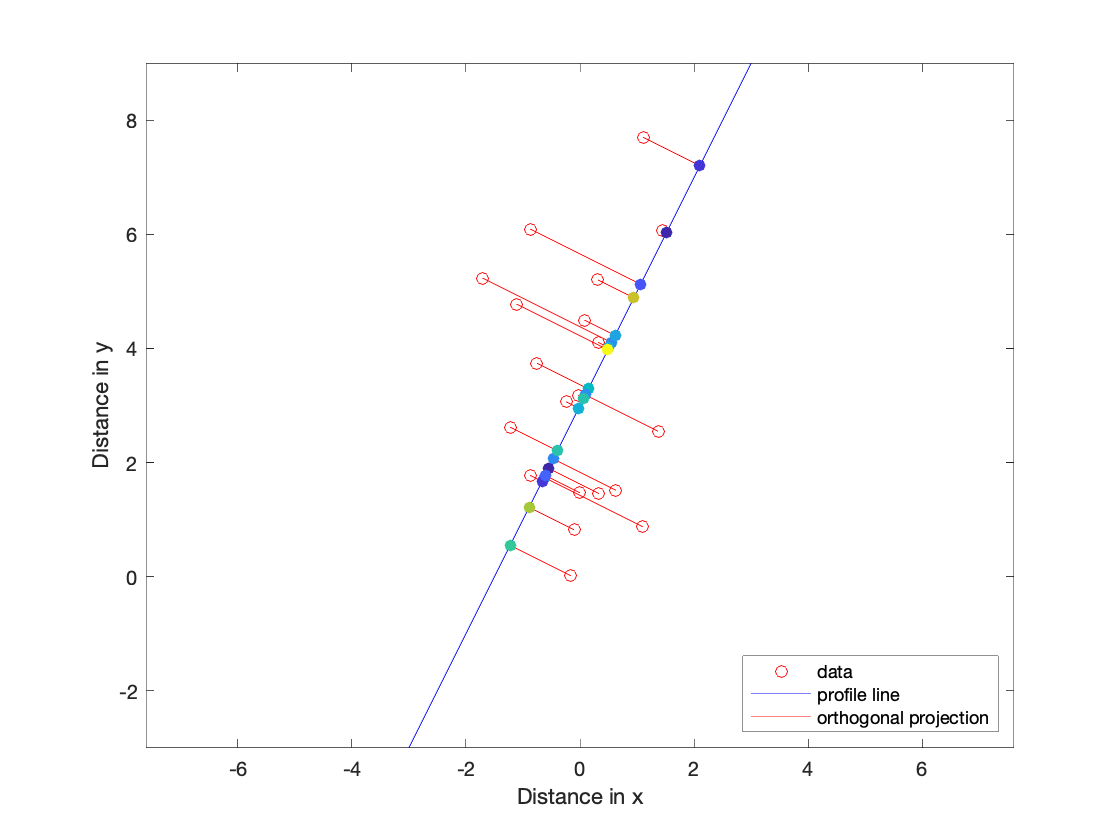

clear all;

% This is our profile line
m = 2;
b = 3;

% compute a random set of locations about the profile line (our data)
x = randn([20 1]);
y = m*randn([20 1]) + b;
% values at (x,y)
v = randn([20 1]);

% compute the profile (for plotting purposes only)
xl = linspace(-3,3,2);
yl = m*xl + b;

% project the data onto a profile
xp = (x + m*(y - b))/(m^2 + 1);
yp = m*xp + b;

figure;
hold on;
plot(x,y,'ro');
plot(xl,yl,'b-');
plot([x xp]',[y yp]','r-');
scatter(xp,yp,36,v,'filled');
xlabel('Distance in x');
ylabel('Distance in y');
legend('data','profile line','orthogonal projection','Location','southeast');
set(gca,'Box','on');
axis square;
axis equal;

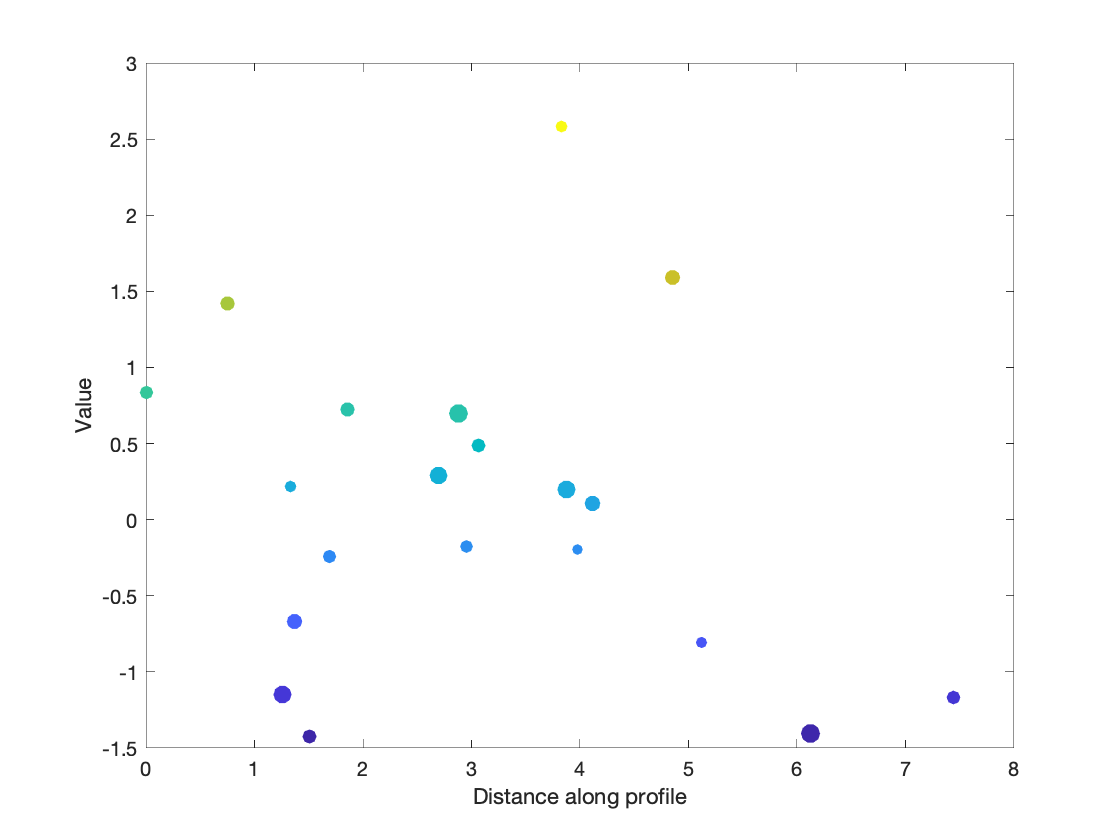


%distance from profile
d = sqrt((x - xp).^2 + (y - yp).^2);

% location of lowest projected x value
[~,ind] = min(xp);

% distance along profile reference to lowest xp
dp = sqrt((xp - xp(ind)).^2 + (yp - yp(ind)).^2);

figure;
scatter(dp,v,100./(d+1),v,'filled');
xlabel('Distance along profile');
ylabel('Value');
set(gca,'Box','on');

### 10.4.2 Gridded Data

Producing a profile from gridded data is relatively straightforward.  For a 2-D grid, you can simply interpolate using the methods described above in Section 10.1.  For 3-D grids, MATLAB includes an interp3() function, but for a profile, you can also use slice() through the data.  One of the nice features of slice() is that you can use it to make cross sections or fence diagrams through a data volume.  An example is given below of a 3-D electrical conductivity model of Kapunda.

### 10.4.3 Projecting Geographic Data

I spent a week during my PhD writing codes to project geographic data and it was some of the most fun that I had (I know...sad).  Projecting geographic data is not so different than projecting irregularly spaced data in Cartesian coordinates, the only difference is that you are on a sphere and need to mind the fact that two longitude values are closer together at higher or lower latitudes than they are at the equator.  As a result, you cannot simply use latitude and longitude values (geographic coordinates) as if they were Cartesian coordinates for projecting.  One way to handle this issue is to project data into a Cartesian reference frame.  One common way to do with is to use a system like the Universal Transverse Mercator (UTM) projection (see Section 10.5).  However, depending on the scale of the profile you desire, this may not be the optimal solution, and with all projections there is some distortion that results.  So I came up with a way to project in geographic coordinates (I'm sure I re-invented the wheel here, but it was fun to do it myself).

The steps involved to project to a are relatively simple, which require a few rotations.

- Rotate one of the ends of the profile to the origin on the equator.  Apply the same rotation to all other points.  This rotation is actually accomplished in two steps, first by rotating to end of the profile to the prime meridian using the south pole as the Euler pole and then rotating along the prime meridian to the origin using a point on the equator as an Euler pole.

- From the new location of the second end of the profile, rotate that point to the equator using the origin as the Euler pole.  Apply the same rotation to all other points.  The profile now sits on the equator and all points are now referenced to the equator.

- Project points along a line of longitude to the projected profile on the equator.

- Compute distances of points along the profile or apply the inverse rotations to place the projected points on the unprojected profile.

## 10.5 Geographic Coordinates and Map Projections

Latitude and longitude is my preferred working coordinate system because it is unambiguous where the data sit on Earth.  Until hologram plotting becomes routine and affordable or everyone owns a plotting sphere to display geographic data, we are stuck using 2-D screens and paper.  Whenever you plot in geographic data on a flat plane, you distort the distances and/or angles between points or the area and/or shape of regions.  A map projection can have an impact on how you interpret data.  However, there is no perfect map projection for all situations.  Which one you chose is dependent upon what you want to show and how large an area you wish to display and any specific requirements about the type or minimization of distortions.  

Map projections fall into three categories:

- Stereographic - projection of the Earth onto a circular plane.  Imagine what the Earth would look like viewed from space.

- Cylindrical - projection to a cylinder wrapped around a great circle of the Earth.

- Conic - projection of a portion of the Earth to the side of a cone tangent to the Earth along a small circle.

There are numbers map projections, we will discuss a few of the more common projections.

### 10.5.1 Mercator Projections

#### 10.5.1.1 Standard Mercator Projection

Mercator projections represent the projection of the Earth onto a cylinder wrapped around the equator with an axis equivalent to Earth's rotational axis.  The Mercator projection is a very common map projection, but is probably best relegated to table placemats because it has such a large distortion near the poles and preserves neither area nor angles.  It can be useful for a rapid display of data, though, why not plot geographic coordinates instead?

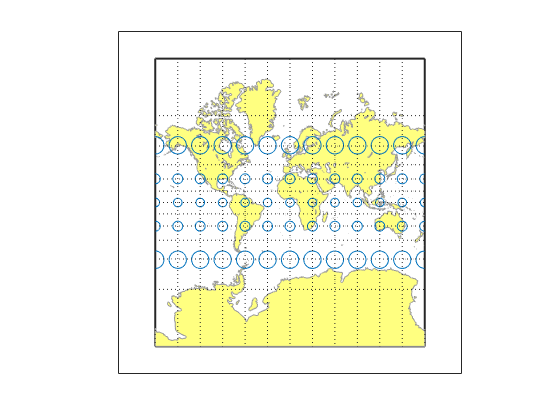

close all;

figure;
landareas = shaperead('landareas.shp','UseGeoCoords',true);
axesm ('mercator', 'Frame', 'on', 'Grid', 'on');
geoshow(landareas,'FaceColor',[1 1 .5],'EdgeColor',[.6 .6 .6]);
tissot;

title('Mercator')

#### 10.5.1.2 Universal Transverse Mercator (UTM)

With many map projections we really want to be able to accurately measure distance and preserve the shape of objects as effectively as possible.  When the area is relatively small it is possible to achieve both aims with a reasonable degree of accuracy using a cylindrical projection that is centered over the region of interest.  However, if everyone centers their projection over their region of interest everyone would be using a different set of coordinates that would make it a nightmare to compare positions of datasets.  In order to solve this problem, geographers developed the universal transverse mercator system (UTM) that uses a standardized set of zones within which coordinates are referenced.  A transverse mercator uses a cylinder that is angled with respect to the Earth's rotational axis and is centered on a latitude and longitude.

A UTM transformation converts latitude and longitude coordinates into Cartesian coordinates where the distances are in meters or kilometers.  The ability to plot locations such that the distances are in a unit that we use to measure distance is a significant advantage over other projections.

One of the issues you may find with UTM coordinates reported in papers is that the datum and zone are frequently not reported.  Also the numbers are quite large—northing is the distance from the equator so it can be quite large—which often leads to authors dropping the first two or three numbers for a small area map, and the last few digits for a large scale map.  These omissions may be fine if you are familiar with the area, but can be quite annoying if you are trying to use reported data in a larger global database.  So if you ever use UTM or AMG below, please report the zone and datum and be very explicit if you drop digits from the coordinates.

#### 10.5.1.3 Australian Map Grid (AMG)

Since we are in Australia, it is important to mention the Australian Map Grid, which is a common map projection used only here.  The AMG is similar to UTM with a few modifications.

In case you are wondering Australia is not the only country that has it's own UTM-like system.  I am familiar with a similar system in use in New Zealand (NZMG) and Brazil and there are probably others. The Scandinavian countries each have their own system that uses a different size for the zones, which they call gons.  One reason a country might want to have its own grid is a more accurate geoid and ellipsoid model tailored to the country.  This results in a more accurate coordinate system that is commonly used by many industries including surveying, civil engineering, construction, petroleum, and mining.

### 10.5.2 Lambert Conic Conformal

The Lambert conic conformal projection is a very common projection for mid-latitudes, and often the preferred projection used by Geoscience Australia when plotting the full continent.  The parameters preferred for Australia are 18$^\circ$S and 36$^\circ$S for the standard parallels.  Full maps of Canada are also frequently projected using a Lambert projection.

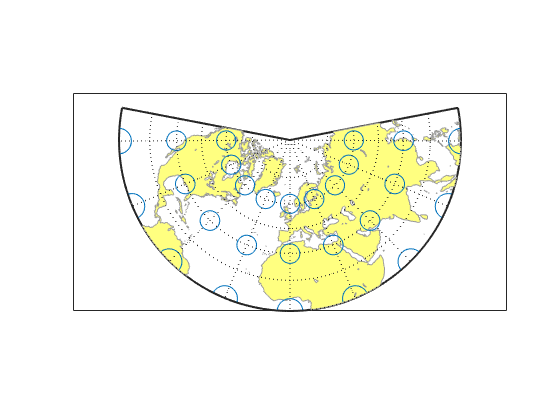

close all;

figure;
landareas = shaperead('landareas.shp','UseGeoCoords',true);
axesm ('lambertstd', 'Frame', 'on', 'Grid', 'on');
geoshow(landareas,'FaceColor',[1 1 .5],'EdgeColor',[.6 .6 .6]);
tissot;

title('Lambert Conic Conformal')

### 10.5.3 Albers Equal Area Conic

The United States and Canada are commonly projected using Albers equal area conic, especially if showing the full North American continent.

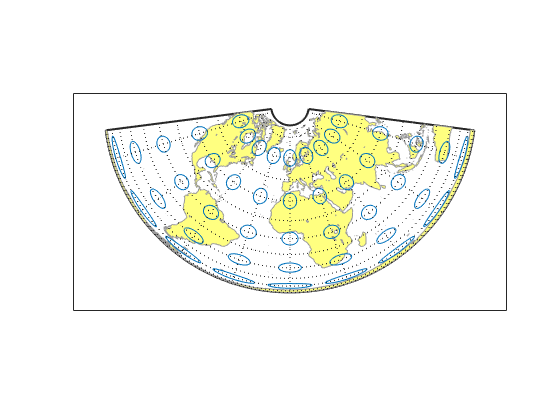

close all;

figure;
landareas = shaperead('landareas.shp','UseGeoCoords',true);
axesm ('eqaconicstd', 'Frame', 'on', 'Grid', 'on');
geoshow(landareas,'FaceColor',[1 1 .5],'EdgeColor',[.6 .6 .6]);
tissot;

title('Albers Equal Area Conic')

### 10.5.5 Robinson

The Robinson projection is a hack of the cylindrical projection as is really pseudo-cylindrical.  The advantage of the Robinson projection is that it produces an unwrapped Earth that "looks right" by producing less distortion near the poles than the Mercator projection.  Generally it is considered pleasing and is a common favorite among atlas makers.

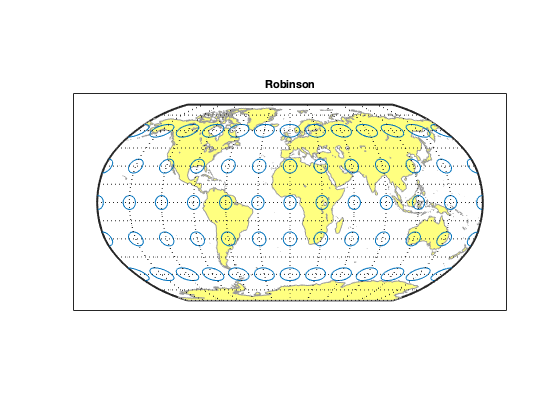

close all;

figure;
landareas = shaperead('landareas.shp','UseGeoCoords',true);
axesm ('ro', 'Frame', 'on', 'Grid', 'on');
geoshow(landareas,'FaceColor',[1 1 .5],'EdgeColor',[.6 .6 .6]);
tissot;
title('Robinson');

### 10.5.6 Polar Stereographic

If you are working in the polar regions (especially Antarctica), you will probably use a polar stereographic projection.

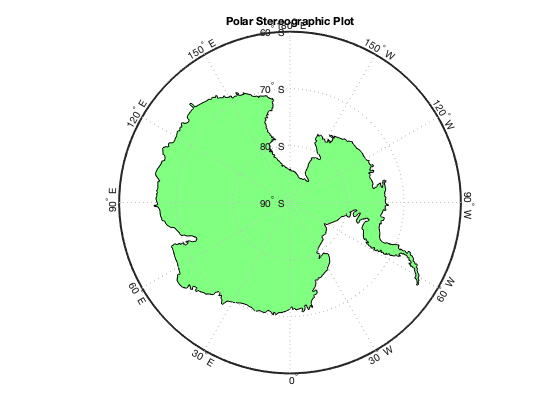

close all;

figure;
map = worldmap([-90,-60],[-180,180]);
antarctica = shaperead('landareas','UseGeoCoords',true,...
    'Selector',{@(name) strcmp(name,'Antarctica'),'Name'});
patchm(antarctica.Lat, antarctica.Lon, [0.5 1 0.5]);
title('Polar Stereographic Plot');

### 10.5.7 Datums

The Earth is not spherical and is more oblate spheriodal (ellipsoidal) in shape to second order.  Therefore we need to be careful with all coordinates and ensure that we know what ellipsoid is used.  